# **矩阵**

创建一个1行6列的矩阵

A = [1 3 8 7 9 5]

A =      1     3     8     7     9     5


矩阵+3

B = A + 3

B =      4     6    11    10    12     8


**plot作图：**索引为横坐标

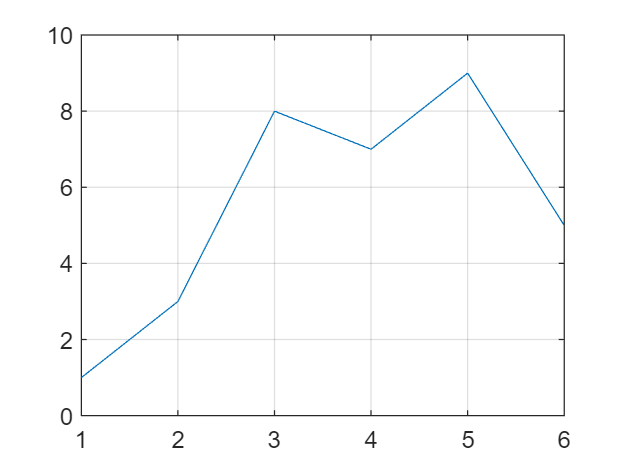

plot(A)
grid on % 网格线

**多维矩阵** ,分隔同一行 ;分隔不同行

C = [1,2,3;4,7,5;9,4,2]

C =      1     2     3
     4     7     5
     9     4     2


% plot(C)

**转置、取逆、特征值、特征向量**

D = C' % 转置

D =      1     4     9
     2     7     4
     3     5     2


[d,V] = eig(C) % 特征值、特征向量  d是特征向量；V是特征值(对角矩阵的每一列)

d =    -0.2905   -0.4465    0.3128
   -0.7737   -0.2355   -0.7600
   -0.5630    0.8633    0.5698


V =    12.1405         0         0
         0   -3.7458         0
         0         0    1.6053


E = inv(C) % 求逆矩阵

E =     0.0822   -0.1096    0.1507
   -0.5068    0.3425   -0.0959
    0.6438   -0.1918    0.0137


F = C*E % 得到单位矩阵

F =     1.0000         0    0.0000
         0    1.0000    0.0000
         0   -0.0000    1.0000


矩阵乘法、点乘

A = [2,1,0;1,0,1]

A =      2     1     0
     1     0     1


B = [1,0,1;0,1,1;0,1,1]

B =      1     0     1
     0     1     1
     0     1     1


B2 = [3,2,1;0,7,3]

B2 =      3     2     1
     0     7     3


C = A*B

C =      2     1     3
     1     1     2


D = A.*C % 点乘，矩阵对应元素相乘

D =      4     1     0
     1     0     2


对**A*x=b**求解，即求**A的逆矩阵乘以矩阵b**

A = [2;4;5]

A =      2
     4
     5


b = [1;3;5]

b =      1
     3
     5


x = A\b % 使用\来求解

x = 0.8667

% \或/，谁在相对较下面的位置谁就是取逆矩阵

MATLAB会将该标量隐式扩展为与另一个操作数具有相同的大小

不同维度的行向量、列向量也能相加

MATLAB会自动补全成相同的行或列数

但一般不要进行这种操作！

A = [1 4 7 8]

A =      1     4     7     8


B = [3;5;6]

B =      3
     5
     6


C = A + B

C =      4     7    10    11
     6     9    12    13
     7    10    13    14
